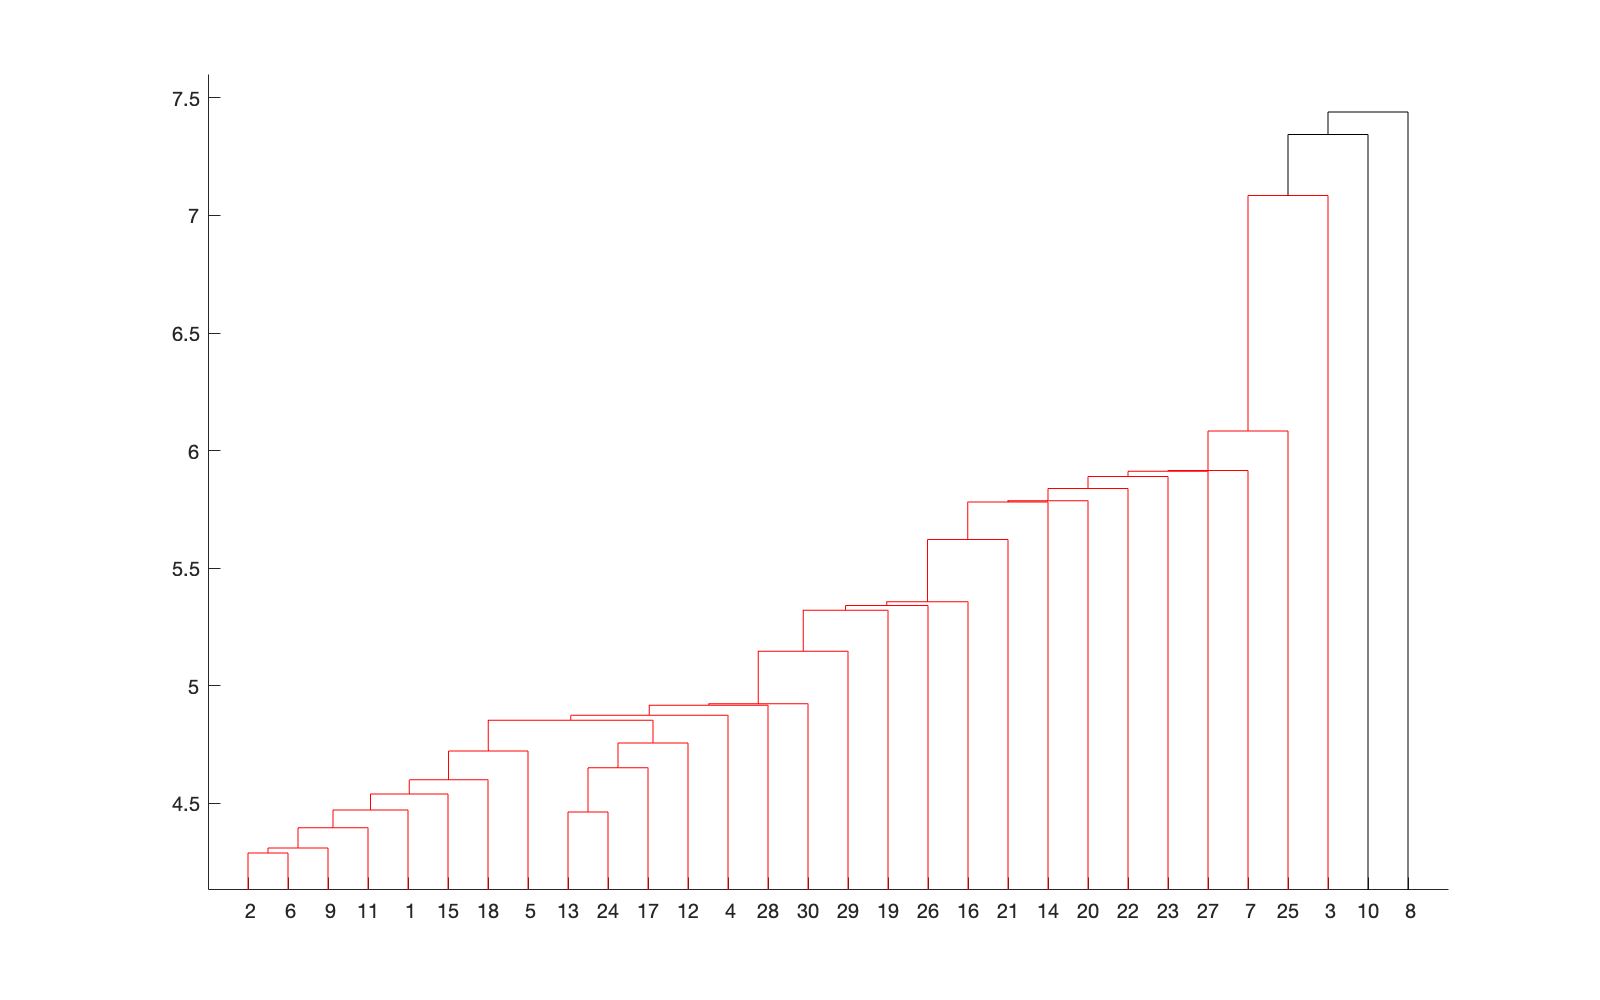

%% Finding MX-ONMTF with modularity density for real networks.
% %for fixed number of common communities, and the number of private and total commmunities per layer.

load("findK_eg2_d5_k6.mat", "kc","k","kp", "Z");

Al = importdata("theta_theta_all.mat");


load("notFixed_eg2_d5_k6.mat", "ClustersSupra");

cutoff = median([Z(end-2,3) Z(end-1,3)]);
dendrogram(Z,'ColorThreshold',cutoff)

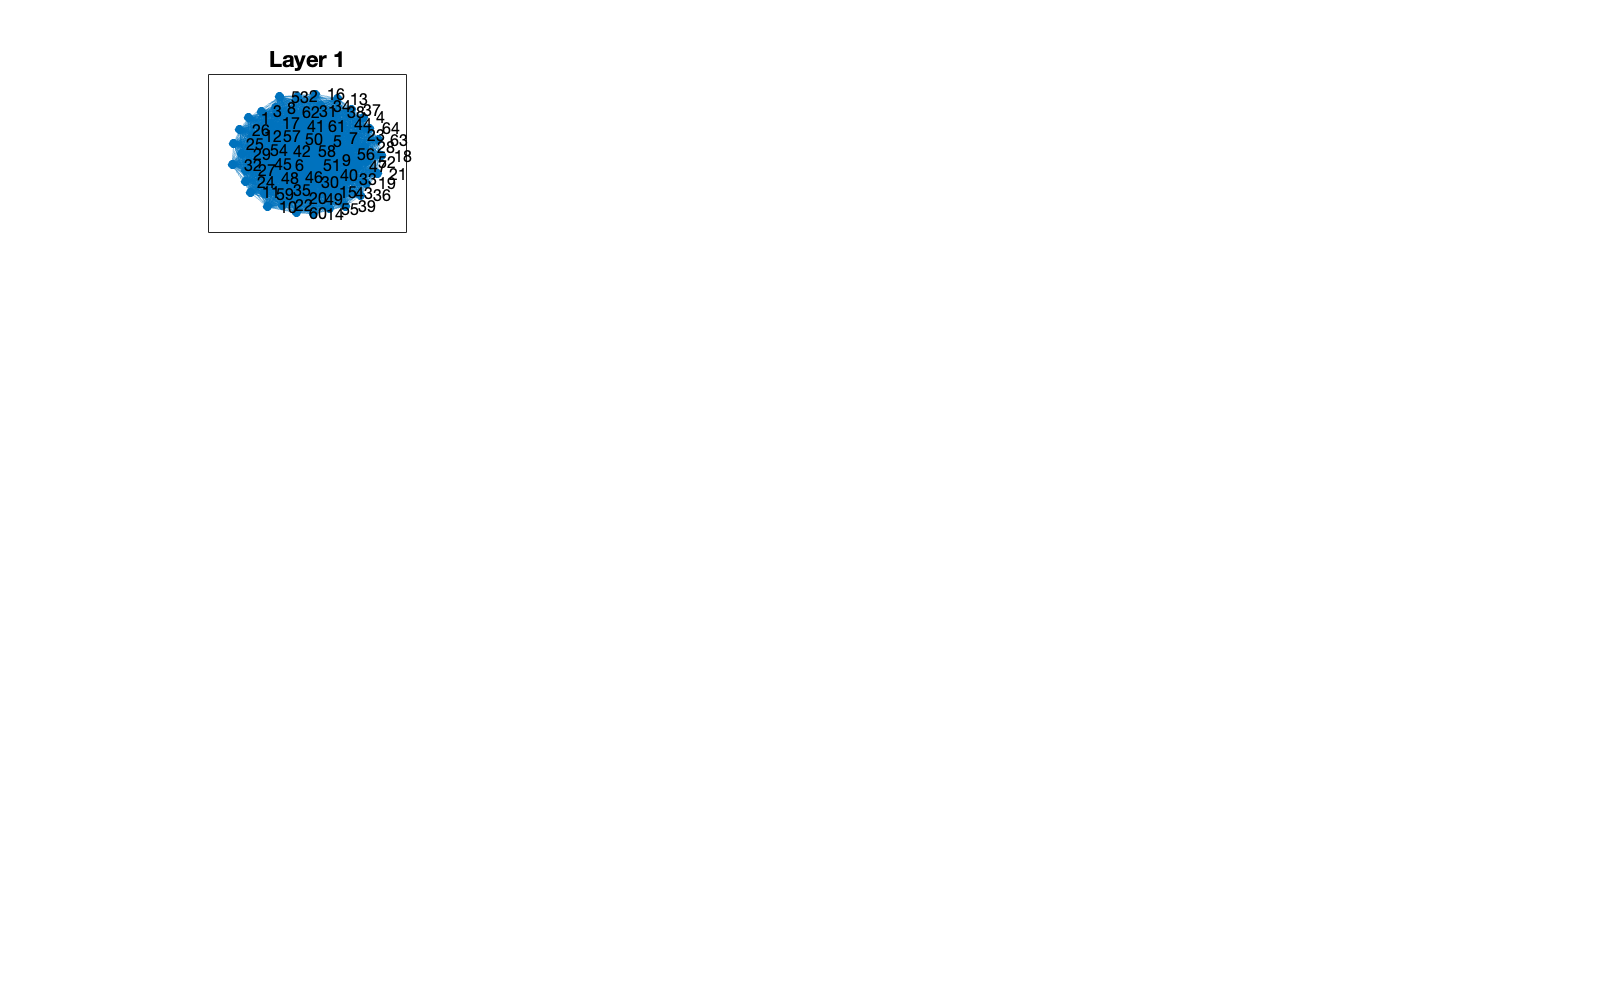


kpl=kp;
ClustersSupra = ClustersSupra; %length(unique(ClustersSupra))
k=k;

unqiue = unique(ClustersSupra);

L = 20; %20 layers
x=1;

%p=plot(graph(Al));
%highlight(p, find(ClustersSupra==k),'NodeColor', 'r' )

for l=1:L
    a= Al{l};
    subplot(4,5,l);
    p=plot(graph(a~=1));
    hold on
    title(sprintf('Layer %d', l));
    %for x=1:kc
    kl = k(1,l); %communities at this layer

    highlight(p, find(ClustersSupra==kl),'NodeColor', 'r' )
    %highlight(p, find(ClustersSupra==x),'NodeColor', 'r' )

    %break
    %end
end


%X = Al; % Noisy 2-D circular data set
%idx = spectralcluster(X,6);
%gscatter(X(:,1),X(:,2),idx);

%g= graph(Al);
%p=plot(graph(Al));
%cluster(p,"maxclust",comm)
    
%T= cluster(Z, 'maxclust', k);
%highlight(p, find(ClustersSupra==k),'NodeColor', 'r' )